# Me mata / T2

## 1: Transformada de Fourier

O sinal $\Delta \left(t\right)$ representa um pulso triangular.


$$\begin{array}{l}
\Delta \left(t\right)\left\lbrace \begin{array}{ll}
0 & t<2,\\
t+2 & -2<t<0,
\end{array}\right.\\
\;\;\;\;\;\;\;\;\;\left\lbrace \begin{array}{ll}
-t+2 & 0<t<2,\\
0 & t>2,
\end{array}\right.
\end{array}$$


## 1.1: Questões

3. Elabore um código Matlab/Octave que verifique se a expressão de $D_n$ obtida no item anterior está correta. Compare com o esperado.

boas práticas:

clc;
clear all;
close all;

g1 = @(t) t+2; 
g2 = @(t) -t+2;
syms t;
x = @(t,n,wo) exp(-j*n*wo*t);
xn = @(t,n,wo) exp(j*n*wo*t);
N = 10;
n = [-N:1:N];
T0 = 4;
wo = (2*pi);

for k = 1:2*N+1 

clc;
c1(k) = projecao(g1(t),x(t,n(k),wo),-2,0);
c2(k) = projecao(g2(t),x(t,n(k),wo),0,2);

end

Res = 1e-3;
tempo1 = [-2:Res:0];
tempo2 = [0:Res:2];
w0 = wo/T0;
pesq = N+1;

for k=1:N

    p1(:,k) = c1(pesq-k)*x(tempo1, n(pesq+k), w0) + c1(pesq+k)*xn(tempo1, n(pesq+k), w0);
    p2(:,k) = c2(pesq-k)*x(tempo2, n(pesq+k), w0) + c2(pesq+k)*xn(tempo2, n(pesq+k), w0);
    r1(:,k) = g1(tempo1)' - sum(p1(:,k));
    r2(:,k) = g2(tempo2)' - sum(p2(:,k));
    totalp1(:,k) = sum(p1(:,k));
    totalp2(:,k) = sum(p2(:,k));

end
totalp1

totalp1 =   405.2847    0.0000   45.0316    0.0000   16.2113   -0.0000    8.2710    0.0000    5.0034   -0.0000


totalp2

totalp2 =   405.2847    0.0000   45.0316   -0.0000   16.2113   -0.0000    8.2710    0.0000    5.0034    0.0000


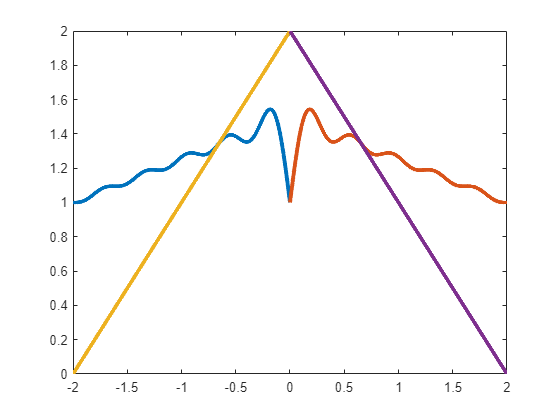

plot(tempo1,sum(p1')+c1(pesq),'LineWidth',3)
hold on;
plot(tempo2,sum(p2')+c2(pesq),'LineWidth',3)
plot(tempo1,g1(tempo1),'LineWidth',3)
plot(tempo2,g2(tempo2),'LineWidth',3)
hold off;

4. Utilizando o mesmo código determine a Banda necessária para que tenhamos 95% da potência do sinal.

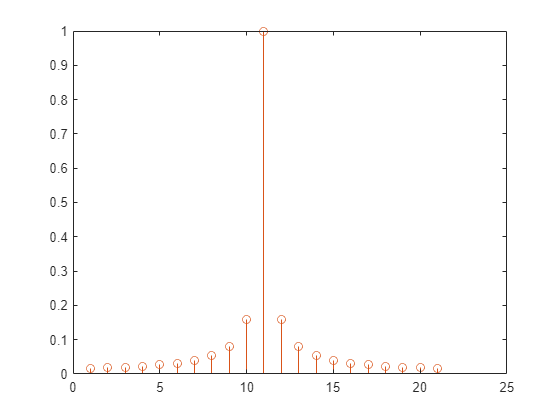

stem(abs(c1))
hold on;
stem(abs(c2))
hold off;

## 2: 